# Conformal Map Test

Given the complexities seen with from the infinite sheet doublet, there will be issues with modelling this flow. Therefore, an alternative solution will be used through the use of a conformal mapping.

## Fourier Series

Required implementation needed for the use of the geometric mapping that will subsequently be used below.

% Tests out the application of a Fourier series by matching a square wave

sqr_wave_freq_factor = 5;
fourier_terms = 21;
time_samples = 5000

time_samples = 5000


t = linspace(0, 2*pi, time_samples);
test_wave = sawtooth(sqr_wave_freq_factor*t, 0.5);

sqr_wave_one_cycle = test_wave(1:round(length(t)/sqr_wave_freq_factor));
t_domain_one_cycle = t(1:round(length(t)/sqr_wave_freq_factor));

% Tests out the Fourier series
[a0, an, bn] = calc_coeffs_ang_fourier_series(sqr_wave_one_cycle, t_domain_one_cycle, fourier_terms);

period
    1.2556



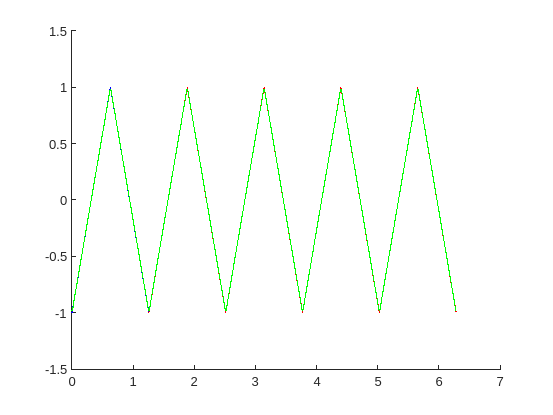

fourier_sqr_wave = calc_vals_from_fourier_series(a0, an, bn, sqr_wave_freq_factor*t);

figure
hold on
plot(t, test_wave, 'r');
plot(t_domain_one_cycle, sqr_wave_one_cycle, 'b')
plot(t, fourier_sqr_wave, 'g');
ylim([-1.5 1.5]);

## Geometric Mapping

Tests out conversion of one shape to another. Nominally this will be needed for only conversion to another shape from a circle given the need to remap flow around this circle to around the arrow body. At this time, the complex plane will be needed as the magnitude and argument change is best represented from the complex plane. Two Fourier transformations will be needed as both the magnitude and argument change in the relation between the 2 positions will be needed.

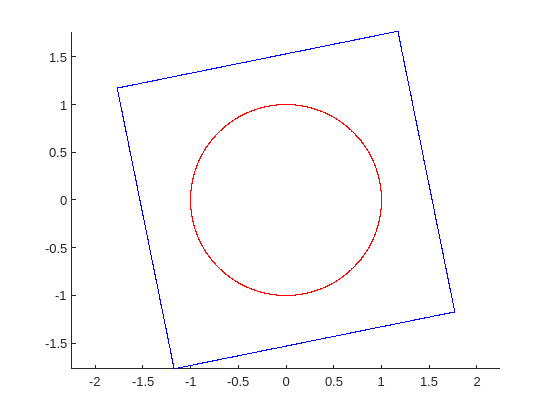

% Defines two arbitrary shapes to try and define a mapping between them

num_ang_steps = 2000;

% Shape 1 - Circle offset from origin
circ_x_offset = 0;
circ_y_offset = 0;
circ_radius = 1;

circ_angs = linspace(0, 2*pi, num_ang_steps);
circ_z_pos = cos(circ_angs) + j*sin(circ_angs);

% Shape 2 - Rotated rectangle at offset
rect_width = 3;
rect_height = 3;
rect_ang = 0.2; % up to 2*pi
rect_x_offset = 0; % center of the rectangle
rect_y_offset = 0; % center of the rectangle

height_locs = linspace(-rect_height/2, rect_height/2, num_ang_steps/4);
width_locs = linspace(-rect_width/2, rect_width/2, num_ang_steps/4);

l_line = -rect_width/2 + j*height_locs;
r_line = rect_width/2 + j*height_locs;

t_line = width_locs + j*rect_height/2;
b_line = width_locs - j*rect_height/2;

rect_z_pos = exp(j*rect_ang)*[r_line t_line(end:-1:1) l_line(end:-1:1) b_line(1:end-1)] + rect_x_offset + j*rect_y_offset;
rect_z_pos = [rect_z_pos rect_z_pos(1)]; % Adds the first item at the end to close the loop

figure
hold on
axis equal
plot(real(circ_z_pos), imag(circ_z_pos), 'r-');
plot(real(rect_z_pos), imag(rect_z_pos), 'b-');


% Given the 1-1 mapping of points, can calculate the magnitude and angle
% between the 2 shapes so we can generate a function

map_circ_to_rect = rect_z_pos ./ circ_z_pos;

mag_diff = abs(map_circ_to_rect);
phase_diff = angle(map_circ_to_rect);

nterms_geo_transform = 25;

[a0_mag, an_mag, bn_mag] = calc_coeffs_ang_fourier_series(mag_diff, circ_angs, nterms_geo_transform);

period
    6.2832



[a0_phase, an_phase, bn_phase] = calc_coeffs_ang_fourier_series(phase_diff, circ_angs, nterms_geo_transform);

period
    6.2832



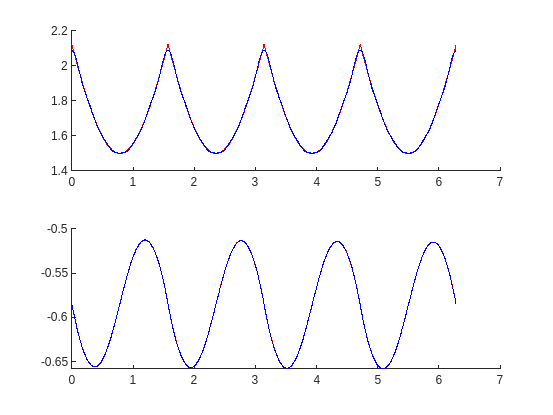


mag_diff_fourier = calc_vals_from_fourier_series(a0_mag, an_mag, bn_mag, circ_angs);
phase_diff_fourier = calc_vals_from_fourier_series(a0_phase, an_phase, bn_phase, circ_angs);

% Plots the magnitude and phase angle and their Fourier series equivalents
% to see how well this mapping can be applied
figure
tiledlayout(2, 1)
nexttile
hold on
plot(circ_angs, mag_diff, 'r');
plot(circ_angs, mag_diff_fourier, 'b');
nexttile
hold on
plot(circ_angs, phase_diff, 'r');
plot(circ_angs, phase_diff_fourier, 'b');


% Need to try out a Fourier transform with complex coefficients to try and
% produce a more generalized function

% [c0, cn, n_cn] = calc_coeffs_cfourier_series(mag_diff, circ_angs, 2*pi, nterms_geo_transform);
% mag_from_fourier = calc_vals_from_cfourier_series(c0, cn, n_cn, 2*pi, circ_angs);
% 
% figure
% hold on
% plot(circ_angs, mag_diff)
% plot(circ_angs, mag_from_fourier);
% legend('Mag diff', 'Mag from Fourier')
% 
% % Circular profile
% circ_angs = circ_angs;
% circ_rads = 1 * ones(1, length(circ_angs));
% 
% % Doesn't work
% [c0_rect_mag, cn_rect_mag, n_cn_rect_mag] = calc_coeffs_cfourier_series(mag_diff, circ_angs, 2*pi, nterms_geo_transform);
% [c0_rect_phase, cn_rect_phase, n_cn_rect_phase] = calc_coeffs_cfourier_series(phase_diff, circ_rads, 2*pi, nterms_geo_transform);
% 
% rect_from_fourier = circ_z_pos .* calc_vals_from_cfourier_series(c0_rect_mag, cn_rect_mag, n_cn_rect_mag, 2*pi, circ_angs) .* ...
%                         calc_vals_from_cfourier_series(c0_rect_phase, cn_rect_phase, n_cn_rect_phase, 2*pi, circ_rads);
% 
% figure
% hold on
% plot(real(rect_from_fourier), imag(rect_from_fourier));


Having problems using the Fourier series. Unfortunately, due to instability with the Fourier series and not being able to feed in a complex value and get an output, we will need to use a differnt model. Will attempt use of a Taylor series to account for other z-values then what is on the grid (although this approach would work if trying to find the streamline directly on the surface of the fin).

Note that the source [https://www.math.wichita.edu/~delillo/TD_tutorial.pdf](https://www.math.wichita.edu/~delillo/TD_tutorial.pdf) (pg. 10-11) suggests that this is a valid method of performing this operation. Hopefully through results it is valid for the external region outside of the arrow.

taylor_order = 20;

rect_coeffs = polyfit(circ_z_pos, rect_z_pos, taylor_order);

% rect_coeffs = calc_coeffs_taylor_series(taylor_order, rect_z_pos, circ_z_pos);

rect_from_taylor = calc_vals_from_taylor_series(rect_coeffs, circ_z_pos);

taylor_ratio = rect_from_taylor ./ circ_z_pos;
taylor_ratio_mag = abs(taylor_ratio);
taylor_ratio_phase_diff = angle(taylor_ratio);

disp('taylor')

taylor


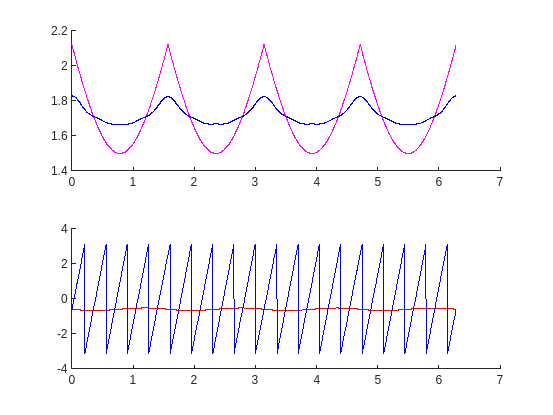

figure
tiledlayout(2, 1);
nexttile
hold on 
plot(circ_angs, mag_diff, 'm');
plot(circ_angs, taylor_ratio_mag, 'b');
nexttile
hold on
plot(circ_angs, phase_diff, 'r');
plot(circ_angs, taylor_ratio_phase_diff, 'b');

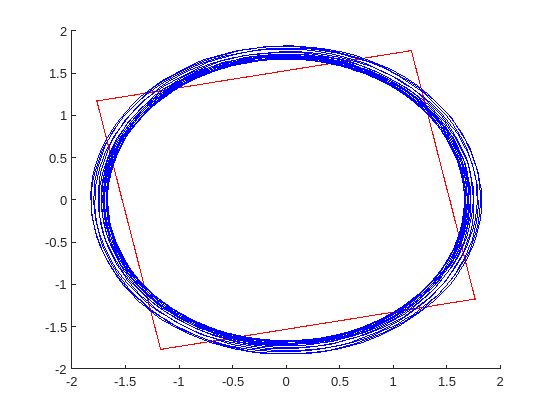


figure
hold on
plot(real(rect_z_pos), imag(rect_z_pos), 'r');
plot(real(rect_from_taylor), imag(rect_from_taylor), 'b');

So polynomial fits are absolute garbage, will try variants of the Taylor series as presened in the tutorial I found through research.

Tutorial suggests that the initial Fourier series needs to be first be solved for the case where $r=1$ given that is allows us to specifically specify the body transformation before adding the consideration of radius.


$$u(r,\theta) = a_0 + \sum_{n=1}^\infty{a_n\cos(n\theta)+b_n\sin(n\theta)}$$


With the radius under consideration:


$$u(r,\theta) = a_0 + \sum_{n=1}^\infty{a_nr^n\cos(n\theta)+b_nr^n\sin(n\theta)}$$


fourier_terms = 20;
period = 2*pi;

def_shape_transf = rect_z_pos ./ circ_z_pos;
[c0_pos, cn_pos, n_cn_pos] = calc_coeffs_cfourier_series(def_shape_transf, circ_angs, period, fourier_terms);

new_rect_frac_fourier = fourier_conf_map_transf(c0_pos, cn_pos, n_cn_pos, circ_z_pos, period);

Not enough input arguments.

Error in fourier_conf_map_transf (line 21)
    zeta = zeta + cn(n) .* rr .^(k_stab*n) .* exp(j*n*pi.*angang/half_period);

new_rect_fourier = circ_z_pos .* new_rect_frac_fourier;

factor_new_circ = 1.05;
new_rect_smaller_fourier = (circ_z_pos * factor_new_circ) .* fourier_conf_map_transf(c0_pos, cn_pos, n_cn_pos, circ_z_pos * factor_new_circ, period);
median_filter_window = 170;

% keep angle on 0 to 2pi
func_fix_angs = @(x) mod(x + 2*pi, 2*pi);


% Design a digital filter
new_rect_smaller_fourier_filt = designfilt('lowpassiir', ...
    'PassbandFrequency',0.025,'StopbandFrequency',0.05, ...
    'PassbandRipple',0.025,'StopbandAttenuation',150, ...
    'MatchExactly','passband');

% Visualize magnitude and phase responses
freqz(new_rect_smaller_fourier_filt.Coefficients)

% Visualize step response
stepz(new_rect_smaller_fourier_filt.Coefficients)
% new_rect_smaller_fourier_filtered = filter(new_rect_smaller_fourier_filt, new_rect_smaller_fourier);
new_rect_smaller_fourier_filtered = new_rect_smaller_fourier; % Disables filtering

% new_rect_smaller_fourier_filt_phase = smoothdata(angle(new_rect_smaller_fourier), 5);
% new_rect_smaller_fourier_filt = new_rect_smaller_fourier_filt_mag .* exp(j*new_rect_smaller_fourier_filt_phase);

figure
tiledlayout(2, 1)
nexttile
hold on
plot(circ_angs, mag_diff, 'r');
plot(circ_angs, abs(def_shape_transf), 'b')
plot(circ_angs, abs(new_rect_smaller_fourier_filtered), 'g');
legend()
nexttile
hold on
plot(circ_angs, phase_diff, 'r');
plot(circ_angs, angle(def_shape_transf), 'b')
plot(circ_angs, angle(new_rect_smaller_fourier_filtered), 'g');
legend()

figure
hold on
axis equal
plot(real(circ_z_pos), imag(circ_z_pos), 'r');
plot(real(new_rect_fourier), imag(new_rect_fourier), 'b');
plot(real(new_rect_smaller_fourier_filtered), imag(new_rect_smaller_fourier_filtered), 'g');

% Got it working!! Might want to employ a low pass filter on the result to
% remove the effect of the ringing on these other values. Either that or
% potentially a correction factor K can be introduced into the magnitude of
% the exponent or value of r in the conformal mapping. Test this when
% actually creating the conformal mapping scheme

% Low pass filter is really hard to get right!, will instead apply a
% reduction factor in the order of n in the fourier conformation map to
% increase stability. This seems to have worked. Can add a simple filter
% later to make profile smooth but this should work well!
